Changing the current folder

cd C:\Users\washi\Documents\

READING DATA FROM EXCEL

%windowSize = 32;
%b = (1/windowSize)*ones(1, windowSize);
%a = 1;

t1= readtable('Book_1.xlsx');
t1 = table2array(t1);
actualThrust = t1(:,1)

actualThrust =          0
    5.9939
    6.5109
    6.9523
    7.4164
    8.1492
    8.7643
    9.5432
   10.3829
   11.3060


time2 = t1(:, 4)

time2 =          0
    0.0300
    0.0600
    0.0900
    0.1200
    0.1500
    0.1800
    0.2100
    0.2400
    0.2700



simthrust = t1(:, 5)

simthrust =          0
  134.0286
  135.7183
  137.3603
  138.9553
  140.5045
  142.0085
  143.4683
  144.8846
  146.2580


time1 = t1(:, 2)

time1 =          0
    0.0125
    0.0250
    0.0375
    0.0500
    0.0625
    0.0750
    0.0875
    0.1000
    0.1125


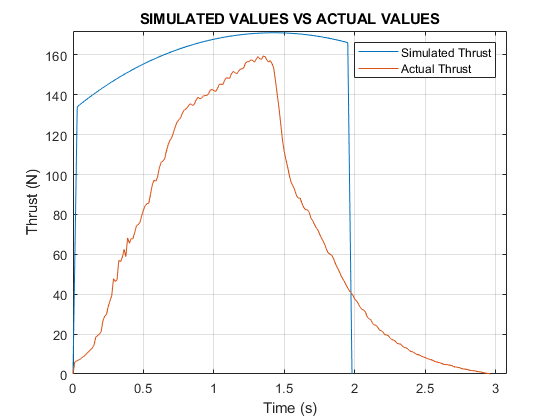


plot(time2, simthrust)
hold on
plot(time1, actualThrust)
legend('Simulated Thrust', 'Actual Thrust')
hold off

xlim([0.00 5.70])
ylim([-2 180])
grid on
title('SIMULATED VALUES VS ACTUAL VALUES')
xlabel('Time (s)')
ylabel('Thrust (N)')

xlim([0.00 3.08])
ylim([-0 172])

max(actualThrust)

ans = 159.4096

filename = "actualthrust.csv"

filename = "actualthrust.csv"

writematrix(actualThrust, filename)

